# Demonstration of a PnP operation for a DGU Network

clear
close all
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));

- Initialize Network: Complete configuration of the network with all the electrical parameters is load from a text file

utils = utilityFunctions;
PnP = SimFunctionsPnP;
config = "DISTRIBUTED"; % distributed config, for plot function
filename = 'config_DGU_1.txt';
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

    {'subsystems'}    {'Vin'}    {'R     '}    {'L     '}    {'C    '}    {'Vmax'}    {'Vmin'}    {'Imax'}    {'Imin'}

    6.0000  100.0000    0.0030    0.0001    0.0001   52.0000   48.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   48.0000   10.0000         0
       NaN  100.0000    0.0017    0.0001    0.0001   52.0000   48.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   48.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   48.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   48.0000   10.0000         0



dguNet = DGU_network(nb_subsystems); % Instantiate a DGU NETWORK class

- Set references $V_r$ [V] to converge to and load current $I_l$ [A]

Vr = linspace(49.95, 50.05, nb_subsystems)% references

Vr =    49.9500   49.9700   49.9900   50.0100   50.0300   50.0500


Il = linspace(3.5, 5.5, nb_subsystems)

Il =     3.5000    3.9000    4.3000    4.7000    5.1000    5.5000


% set Electrical parameters and Dynamics for ALL the subsystems in the network
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end

### A) For now consider only 5 active DGU out of 6

Parameters for MPC simulation

simStart = 1;
length_sim = 15;

Network Configuration

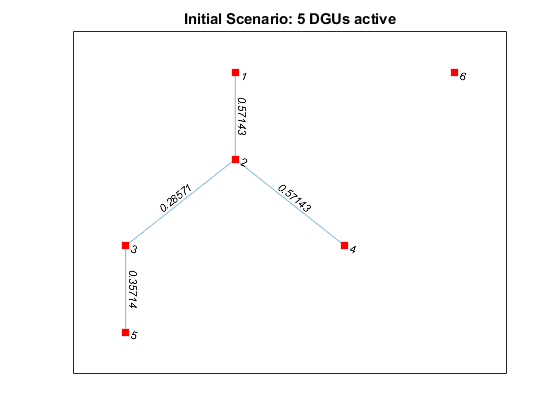

activeDGU_scen1 = 1:1:5; % Initially, 5 DGUs are active
Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8; 
Rij_mat = Rij_mat + tril(Rij_mat',1); % Non directed graph, symmetric matrix
dguNet = dguNet.setConnectionsGraph(Rij_mat); % set links between DGU
dguNet = dguNet.setActiveDGU(activeDGU_scen1); % define which DGUs are active
figure()
plot(dguNet.NetGraph, 'EdgeLabel', dguNet.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title("Initial Scenario: 5 DGUs active");

dguNet = dguNet.initDynamics(); % initialize dynamics

For passivity based MPC, constraints are not in $\Delta$ Formulation 

delta_config = false; % not in delta configuration
dguNet = dguNet.compute_Ref_Constraints(delta_config);

- Use passivity to find the local passive feedback gains $K_i$ and $P_i$ s.t. $V_i(x_i) = x_i^T P_i x_i$

dguNet = PnP.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312



ans = "K2"

   -0.0107   -0.1036



ans = "P2"

    2.9563    0.5613
    0.5613    4.2433



ans = "K3"

   -0.4957   -0.1504



ans = "P3"

   24.7525    2.1796
    2.1796    1.0426



ans = "K4"

   -0.1109   -0.0993



ans = "P4"

   11.3549    1.3674
    1.3674    1.7662



ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6916
    4.6916    1.6810

Smallest among all subsystem minimum eigenvalue of dissipation rate 9.97e-02 


Compute Qi and Ri matrices in a distributed fashion to ensure global aymptotic stability

passivity = true;
[x0, Q_Ni, Ri, Qi, decVar] = utils.tuningParam(dguNet, delta_config, passivity);

Qi and Ri found to guarantee asympt. stability of the global system 


- Use the tracking MPC with reconfigurable terminal ingredients  to converge to reference from the initial state

control_type = "MPC with reconfigurable terminal ingredients";
[X, U, ~] = PnP.mpc_DGU_tracking(@trackingMPC_reconf, x0, length_sim,...
                                             dguNet, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf -- 
 ---- Simulation step 1 ---- 
---- Simulation step 2 ---- 
---- Simulation step 3 ---- 
---- Simulation step 4 ---- 
---- Simulation step 5 ---- 
---- Simulation step 6 ---- 
---- Simulation step 7 ---- 
---- Simulation step 8 ---- 
---- Simulation step 9 ---- 
---- Simulation step 10 ---- 
---- Simulation step 11 ---- 
---- Simulation step 12 ---- 
---- Simulation step 13 ---- 
---- Simulation step 14 ---- 
---- Simulation step 15 ---- 
Max time per iteration for simulation time = 2.813890e-02 


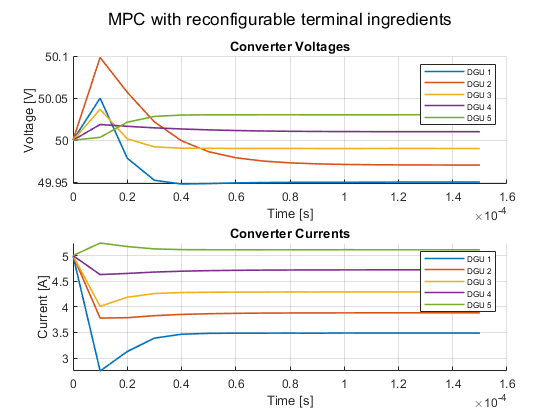

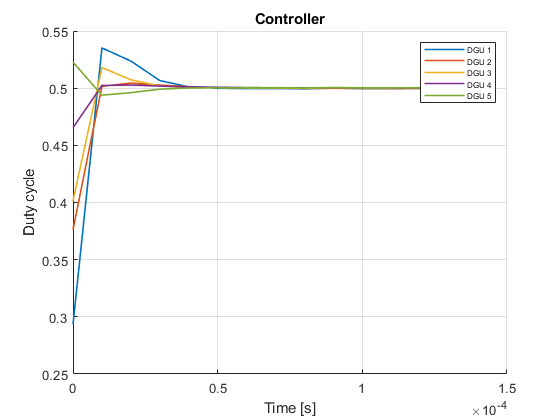

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart, dguNet.activeDGU); % plot results

- **Compare to **$\Delta$ **Formulation with offline computed terminal set and terminal cost**

delta_config = true;
use_passivity = false;
[x0_delta, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config, use_passivity);
dguNet_delta = dguNet;
dguNet_delta = dguNet_delta.compute_Ref_Constraints(delta_config);
[dguNet_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724         0         0         0    0.2862   -0.0000    0.5724         0



ans = "Local feedback control laws K_N3"

   1.0e-03 *

    0.2555    0.0000         0         0    0.3194         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615    0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



fprintf("Initial terminal set constrait alpha = %d \n", alpha_i)

Initial terminal set constrait alpha = 6.031131e-01 


alpha = alpha_i*ismember(1:6, dguNet_delta.activeDGU)';
[Xdelt,Udelt, ~] = PnP.mpc_sim_DGU_delta(@mpc_delta, x0_delta, length_sim, dguNet_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);

--INFO: Using controller mpc_delta -- 
 ---- Simulation step 1 ---- 
---- Simulation step 2 ---- 
---- Simulation step 3 ---- 
---- Simulation step 4 ---- 
---- Simulation step 5 ---- 
---- Simulation step 6 ---- 
---- Simulation step 7 ---- 
---- Simulation step 8 ---- 
---- Simulation step 9 ---- 
---- Simulation step 10 ---- 
---- Simulation step 11 ---- 
---- Simulation step 12 ---- 
---- Simulation step 13 ---- 
---- Simulation step 14 ---- 
---- Simulation step 15 ---- 
Max time per iteration for simulation time = 4.925000e-03 


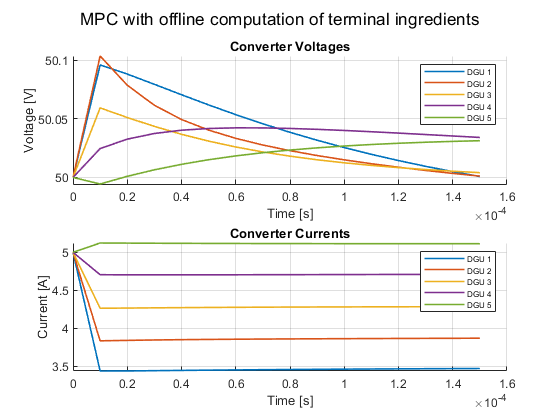

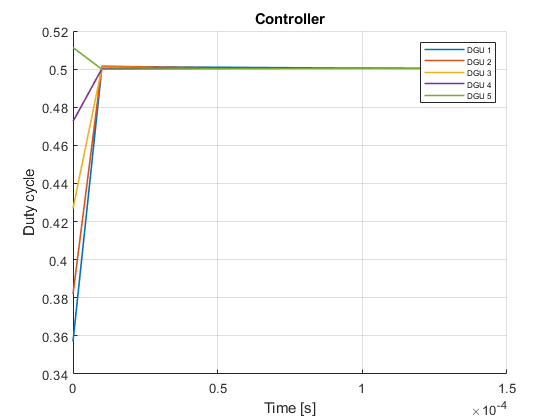

control_type = "MPC with offline computation of terminal ingredients";
config = "DISTRIBUTED";
simStart = 1;
dguNet.plot_DGU_system(Xdelt,Udelt, config, control_type, dguNet_delta, simStart, dguNet_delta.activeDGU)

### B) Scenario 2: Connect DGU 6 to DGU 3

Set all DGUs to be active. DGU 6 is now active but is not connected yet to the network

simStart2 = simStart + length_sim;
dguPos = 6;
activeDGU_scen2 = 1:1:6; % Now all the 6 DGUs are active
dguNet = dguNet.setActiveDGU(activeDGU_scen2);
dguNet2 = dguNet; % dguNet copy, with 6 active DGU but before connection

Create connection from DGU 6 to DGU 3. For this purpose, a new instance of the network class is created with the modified structure e.g. different Laplacian matrix and $A_{Ni}$ 

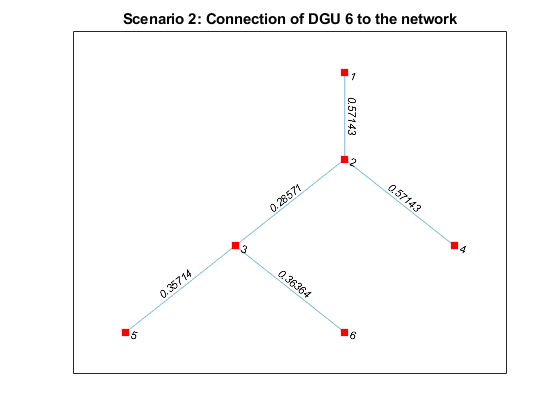

Rij_mat(3,dguPos) = 2.75; Rij_mat(dguPos,3) = Rij_mat(3,dguPos);  % New link
dguNet2 = dguNet2.setConnectionsGraph(Rij_mat);
dguNet2 = dguNet2.initDynamics(); % recompute Dynamics (changed with integration of DGU 6)
plot(dguNet2.NetGraph, 'EdgeLabel', dguNet2.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario 2: Connection of DGU 6 to the network')

#### **PnP with passivity and Online computation of Terminal Ingredients**

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 6 (including DGU 6 itself)

use_passivity = true;
delta_config = false;
dguNet2 = dguNet2.compute_Ref_Constraints(delta_config);
[dguNet2, Qi, Ri, Q_Ni, decVar] = PnP.redesignPhase(dguNet2, dguNet2.NetGraph,dguPos, "add", Qi, Ri, decVar);

ans = "New passive controller gain of system 3"

   -0.4649   -0.1511



ans = "P3"

   15.8061    1.3571
    1.3571    0.6737

minimum eigenvalue of dissipation rate 5.26e-01 


ans = "New passive controller gain of system 6"

   -0.5574   -0.1421



ans = "P6"

   53.5936    4.1295
    4.1295    1.6485

minimum eigenvalue of dissipation rate 1.29e+00 
Qi and Ri found to guarantee asympt. stability of the global system 
Qi and Ri found to guarantee asympt. stability of the global system 


Re-define Q_Ni since neighbors of DGU 3 and 6 changed. Initial values for the 5 first DGUs taken from previous simulation end. 

%[x0, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet2, delta_config, use_passivity); 
x0{6} = [50; 5-Il(6)]

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


for i = activeDGU_scen1
    x0{i} = X{end}(:,i);   %
end
disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   49.9502
   -0.0116

 
 
x0{2} =
 
   49.9704
   -0.0168

 
 
x0{3} =
 
   49.9901
   -0.0086

 
 
x0{4} =
 
   50.0100
    0.0226

 
 
x0{5} =
 
   50.0302
    0.0143

 
 
x0{6} =
 
   50.0000
   -0.5000

 


- **Transition Phase**: Compute steady-state value to reach to allow the plug-in of DGU 6 (*PnP permitted). *Drive the system (the 5 initial DGU's + the 6th DGU before connection) to this steady state.

ADMM = true; regulation = true;
[X2_trans,U2_trans,lenSim, xs,us,alpha] = PnP.transitionPhase(x0, dguNet, dguNet2, Qi, Ri, 'current state', ADMM,regulation)

Using ADMM !


Error using transition_compute_ss_admm>local_optim (line 167)
Steady-state not found, Optimization problem: P&P rejected

Error in transition_compute_ss_admm (

Initial states for reference MPC tracking are the states from the end of the transition phase (i.e. corresponding to steady state where P&P permitted):

for i = activeDGU_scen2
    x0{i} = X2_trans{end}(:,i);   
end
lenSim2 = 20;
annot2plot.array = dguNet2.Ts*[simStart2-1,simStart2+lenSim-1];
annot2plot.text = {'Start', 'End'};
[X2, U2] = PnP.mpc_DGU_tracking(@trackingMPC_reconf, x0, lenSim2, dguNet2, Q_Ni, Ri);
control_type = "Plug in of DGU 6";
dguNet2.plot_DGU_system([X(1:end-1),X2_trans,X2(1:end)],[U, U2_trans, U2(1:end)], config, control_type, dguNet2, simStart, activeDGU_scen2, annot2plot); % plot results

#### Test PnP with offline terminal ingredients

dguNet_delta = dguNet_delta.setActiveDGU(activeDGU_scen2); 
dguNet2_delta = dguNet2;
delta_config = true;
dguNet2_delta = dguNet2_delta.compute_Ref_Constraints(delta_config);
use_passivity = false;
[x0_delta, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet2_delta, delta_config, use_passivity);
[dguNet2_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet2_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724    0.0000         0         0    0.2862    0.0000    0.5724    0.0000



ans = "Local feedback control laws K_N3"

   1.0e-03 *

    0.2555   -0.0000         0         0    0.3194   -0.0000    0.3252         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615   -0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



ans = "Local feedback control laws K_N6"

   1.0e-03 *

    0.2937         0         0         0



fprintf("Initial terminal set constrait alpha = %d \n", alpha_i)

Initial terminal set constrait alpha = 1.205337e-01 


alpha = alpha_i*ismember(1:6, dguNet2_delta.activeDGU)';
length_sim = 30;
[X2trans_delt, U2trans_delt,lenSim, xs,us] = PnP.transitionPhaseDeltaADMM(x0_delta, dguNet_delta,...
                                  dguNet2_delta, Qi, Ri, 'reference', alpha);
for i = activeDGU_scen2
    x0_delt{i} = X2trans_delt{end}(:,i);   
end
lenSim2 = 25;
annot2plot.array = dguNet2_delta.Ts*[simStart2,simStart2+lenSim];
annot2plot.text = {'Start Transition Phase', 'End Transition Phase'};
control_type = "MPC with offline terminal ingredients";
[X2delt, U2delt] = PnP.mpc_sim_DGU_delta(@mpc_delta_admm, x0_delt, lenSim2, dguNet2_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);
dguNet2.plot_DGU_system([Xdelt(1:end-1),X2trans_delt,X2delt],...
                        [Udelt, U2trans_delt, U2delt], config, control_type, dguNet2_delta, simStart, ...
                        activeDGU_scen2, annot2plot); % plot results

#### C) 3rd Scenario: Plug out DGU 4

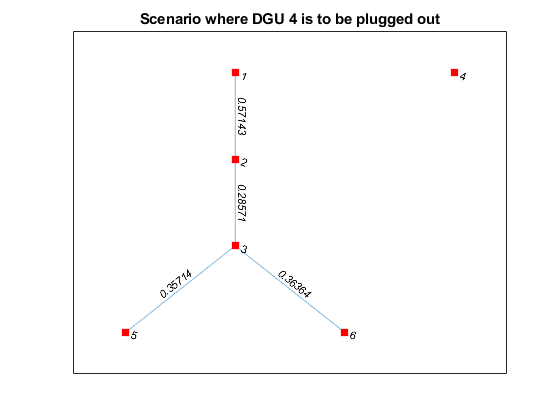

activeDGU_scen3 = [1 2 3 5 6]; % remove DGU 4 from active DGU list
dguNet3 = dguNet2; % copy the previous instance with 6 DGUs and create new instance for this scenario
dguNet3 = dguNet3.setActiveDGU(activeDGU_scen3);
dguDelete = 4;
Rij_mat(dguDelete,:) = 0; Rij_mat(:,dguDelete) = 0;
dguNet3 = dguNet3.setConnectionsGraph(Rij_mat);
dguNet3 = dguNet3.initDynamics();
plot(dguNet3.NetGraph, 'EdgeLabel', dguNet3.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario where DGU 4 is to be plugged out')

delta_config = false;
dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 4

[dguNet3, Qi,Ri,Q_Ni,decVar] = PnP.redesignPhase(dguNet3, dguNet2.NetGraph, dguDelete, "delete", Qi,Ri, decVar);

ans = "New passive controller gain of system 2"

   -0.0362   -0.1044



ans = "P2"

    4.0946    0.7040
    0.7040    2.4496

minimum eigenvalue of dissipation rate 2.21e-01 
Qi and Ri found to guarantee asympt. stability of the global system 
Qi and Ri found to guarantee asympt. stability of the global system 


- **Transition Phase**: Take as initial state the end of simulation of scenario 2

% % call again since dimension of Q_Ni change when adding/removing DGU
% [~, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet3, delta_config);
for i = activeDGU_scen2
    %x0{i} = X2{end}(:,i);   
    Idrop = 1/2*(i-1)*(-1)^i
%     Idrop = 0;
     x0{i} = [50; 5 + Idrop - Il(i)]
%     x0_delta{i} = [Vr(i); Il(i)]
end

Idrop = 0

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = 0.5000

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = -1

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = 1.5000

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = -2

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = 2.5000

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   50.0000
    1.5000

 
 
x0{2} =
 
   50.0000
    1.6000

 
 
x0{3} =
 
   50.0000
   -0.3000

 
 
x0{4} =
 
   50.0000
    1.8000

 
 
x0{5} =
 
   50.0000
   -2.1000

 
 
x0{6} =
 
    50
     2

 


Define new references, to see the effect of the objective function of the optimization problem:

dguNet2_delta = dguNet2;
dguNet2_delta = dguNet2_delta.compute_Ref_Constraints(true);
dguNet3_delta = dguNet3;
dguNet3_delta = dguNet3_delta.compute_Ref_Constraints(true);
[dguNet3_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet3_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724         0         0         0    0.2862   -0.0000



ans = "Local feedback control laws K_N3"

   1.0e-03 *

    0.2555    0.0000         0         0    0.3194   -0.0000    0.3252   -0.0000



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



ans = "Local feedback control laws K_N6"

   1.0e-03 *

    0.2937         0         0         0



alpha = alpha_i*ismember(1:6, dguNet3_delta.activeDGU)';
%[X3trans_delt, U3trans_delt,lenSim, xs,us] = PnP.transitionPhaseDeltaADMM(x0_delta, dguNet2_delta,...
                             %     dguNet3_delta, Qi, Ri, 'reference', alpha);
% dguNet3.Vr = linspace(49.90, 50.4, nb_subsystems);% references
% dguNet3.Il = linspace(2.5, 7.5, nb_subsystems);
% dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_0^i ||}^2$ will keep the steady state as close as possible to the current state: for quick P&P operation

ADMM = true; regulation = true;
[X3_trans,U3_trans,lenTrans, xs,us,alpha]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'reference', ADMM, regulation)

Using ADMM !
Iteration 1,  Max system time elapsed for each ADMM iteration is 3.297000e-03 
Iteration 2,  Max system time elapsed for each ADMM iteration is 6.869500e-03 
Iteration 3,  Max system time elapsed for each ADMM iteration is 4.653900e-03 
Iteration 4,  Max system time elapsed for each ADMM iteration is 4.615400e-03 
Iteration 5,  Max system time elapsed for each ADMM iteration is 2.920900e-03 
Iteration 6,  Max system time elapsed for each ADMM iteration is 2.924800e-03 
Iteration 7,  Max system time elapsed for each ADMM iteration is 2.927300e-03 
Iteration 8,  Max system time elapsed for each ADMM iteration is 4.826000e-03 
Iteration 9,  Max system time elapsed for each ADMM iteration is 2.932800e-03 
Iteration 10,  Max system time elapsed for each ADMM iteration is 2.783300e-03 
Iteration 11,  Max system time elapsed for each ADMM iteration is 2.744000e-03 
Iteration 12,  Max system time elapsed for each ADMM iteration is 2.973300e-03 
Iteration 13,  Max system time elaps

X3_trans = 1×9 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U3_trans = 1×8 cell array
    {[0.3071 0.3189 0.5261 0.3012 0.7294 0.2910]}    {[0.5133 0.5027 0.5019 0.5078 0.5066 0.5002]}    {[0.5247 0.5069 0.4983 0.5116 0.4767 0.5169]}    {[0.5109 0.5042 0.4992 0.5068 0.4862 0.5076]}    {[0.5030 0.5023 0.4999 0.5039 0.4951 0.5023]}    {[0.5003 0.5012 0.5001 0.5022 0.4990 0.5007]}    {[0.4997 0.5005 0.5001 0.5013 0.5002 0.5004]}    {[0.4996 0.5002 0.5000 0.5007 0.5004 0.5005]}


lenTrans = 9

xs =    49.9496   49.9697   49.9901   50.0100   50.0297   50.0497
   -0.0111   -0.0179   -0.0301    0.0231    0.0142    0.0217


us =     0.4995    0.4997    0.4999    0.5001    0.5003    0.5005


alpha =      0
     0
     0
     0
     0
     0


$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_r^i ||}^2$ will keep the steady state as close as possible from the references, with the goal of reducing modification to the desired system behaviour

% [X3_trans,U3_trans,lenTrans, xs,us,alpha]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'reference', ADMM)

If P&P permitted, simulate normal operation of the network after plug out of DGU 4:

for i = activeDGU_scen3
    x0{i} = X3_trans{end}(:,i);   
end
lenSim3 = 5;
[X3, U3] = PnP.mpc_DGU_tracking(@trackingMPC_reconf, x0, lenSim3, dguNet3, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf -- 
 ---- Simulation step 1 ---- 
---- Simulation step 2 ---- 
---- Simulation step 3 ---- 
---- Simulation step 4 ---- 
---- Simulation step 5 ---- 
Max time per iteration for simulation time = 8.799000e-03 


annot2plot.array = dguNet3.Ts*[0,lenTrans-1];
annot2plot.text = {'Start', 'End'};
% plot the last 11 points from the previous phase
control_type = "Plug out of DGU 4"

control_type = "Plug out of DGU 4"

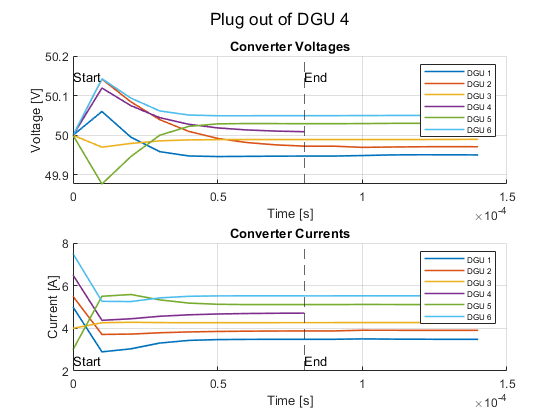

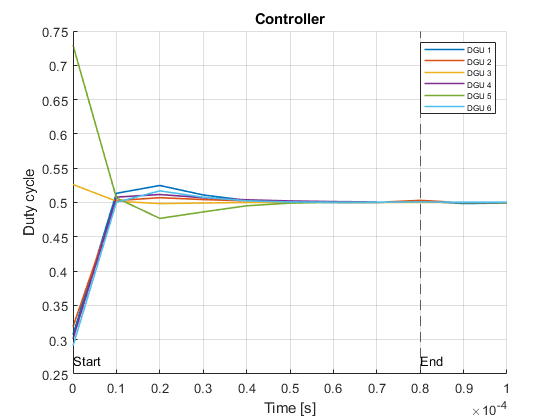

dguNet3.plot_DGU_system([X3_trans, X3],[U3_trans, U3], config, ...
                control_type, dguNet3, simStart, activeDGU_scen2, annot2plot); % plot results